## **UVP5-UVP6 intercalibration**

clear all
close all

global project_folder_ref project_folder_adj results_dir_ref datahistref...
     ref_esd_calib_log fit_type...
    pix_ref pix_adj X0 rec_ref rec_adj base_ref base_adj...
    aa_data_ref expo_data_ref img_vol_data_ref img_vol_data_adj aa_adj...
    expo_adj ref_histo_mm2_vol_mean uvp_ref uvp_adj gain_adj Thres_adj Exposure_adj...
    ShutterSpeed_adj SMBase_adj gain_ref Thres_ref Exposure_ref...
    ShutterSpeed_ref SMBase_ref  light1_ref light2_ref light1_adj light2_adj...
    adj_histo_mm2_vol_mean   Fit_range...

disp('Version 2019/06/11')

Version 2019/06/11


## Analyse date

disp(['Processing date : ',datestr(now,31)])

Processing date : 2020-03-25 16:58:13


## Analyse operator

people = input('Enter people first and last name (default : Marc Picheral)','s');
if isempty(people); people = 'Marc Picheral'; end
disp(['Processing operator : ' char(people)]);

Processing operator : Marc Picheral


## Selection of REFERENCE instrument and data

[project_folder_ref,results_dir_ref,base_ref,rec_ref,uvp_ref] = Ouverture_base_calibration('Reference');

>> Select UVP Reference project directory
----------- Base list --------------------------------
1 database in Y:\uvp5_sn002_intercalibrage_bassin_20180815\results\
N°= 1 : baseuvp5_sn002_intercalibrage_bassin_20180815_cal.mat
------------------------------------------------------
Number : 1   >  Profile : 002_f
Number : 2   >  Profile : 002_g
Number : 3   >  Profile : 002_h
Number : 4   >  Profile : 002_i
Number : 5   >  Profile : 002_j
Number : 6   >  Profile : 002_k
Number : 7   >  Profile : 002_l
Number : 8   >  Profile : 002_m
Number : 9   >  Profile : 002_n



if (strcmp(project_folder_ref(4:7),'uvp5'))
    % Reading uvp5_configuration_data.txt REF
    
    filename=[project_folder_ref,'\config\uvp5_settings\uvp5_configuration_data.txt'];
    [ aa_data_ref,expo_data_ref,img_vol_data_ref,pix_ref,light1_ref,light2_ref] = read_uvp5_configuration_data( filename ,'data' );
    % Reading *.hdr REF
    
    filename=[project_folder_ref,'\raw\HDR',char(base_ref(rec_ref).histfile),'\HDR',char(base_ref(rec_ref).histfile),'.hdr'];
    [ a,b,c,d,l1,l2,gain_ref,Thres_ref,Exposure_ref,ShutterSpeed_ref,SMBase_ref] = read_uvp5_configuration_data( filename , 'hdr');
else
    % Reading data from UVP6 base
    aa_data_ref = base_ref(rec_ref).a0;
    expo_data_ref = base_ref(rec_ref).exp0;
    img_vol_data_ref = base_ref(rec_ref).volimg0;
    pix_ref = base_ref(rec_ref).pixel_size;
    gain_ref = base_ref(rec_ref).gain;
    Thres_ref = base_ref(rec_ref).threshold;
    Exposure_ref = base_ref(rec_ref).shutter;
    ShutterSpeed_ref = base_ref(rec_ref).shutter;
    SMBase_ref    = 1;
end

## Selection of instrument and data to adjust

[project_folder_adj,results_dir_adj, base_adj, rec_adj, uvp_adj] = Ouverture_base_calibration('Adjusted');

>> Select UVP Adjusted project directory
----------- Base list --------------------------------
1 database in Y:\uvp5_sn210_intercalibrage_bassin_20181012\results\
N°= 1 : baseuvp5_sn210_intercalibrage_bassin_20181012_cal.mat
------------------------------------------------------
Number : 1   >  Profile : 210_a
Number : 2   >  Profile : 210_b
Number : 3   >  Profile : 210_c
Number : 4   >  Profile : 210_d
Number : 5   >  Profile : 210_e
Number : 6   >  Profile : 210_f
Number : 7   >  Profile : 210_g
Number : 8   >  Profile : 210_h
Number : 9   >  Profile : 210_i
Number : 10   >  Profile : 210_j
Number : 11   >  Profile : 210_k
Number : 12   >  Profile : 210_l
Number : 13   >  Profile : 210_m
Number : 14   >  Profile : 210_n



if (strcmp(project_folder_adj(4:7),'uvp5'))
    % Reading uvp5_configuration_data.txt ADJ

    filename=[project_folder_adj,'\config\uvp5_settings\uvp5_configuration_data.txt'];
    [ aa_data_adj, expo_data_adj, img_vol_data_adj, pix_adj, light1_adj ,light2_adj] = read_uvp5_configuration_data( filename , 'data');

    filename=[project_folder_adj,'\raw\HDR',char(base_adj(rec_adj).histfile),'\HDR',char(base_adj(rec_adj).histfile),'.hdr'];
    [ a ,b ,c, d, l1, l2, gain_adj, Thres_adj, Exposure_adj, ShutterSpeed_adj, SMBase_adj] =  read_uvp5_configuration_data( filename , 'hdr');
else
    % Reading data from UVP6 base
    aa_data_adj = base_adj(rec_adj).a0;
    expo_data_adj = base_adj(rec_adj).exp0;
    img_vol_data_adj = base_adj(rec_adj).volimg0;
    pix_adj = base_adj(rec_adj).pixel_size;
    gain_adj = base_adj(rec_adj).gain;
    Thres_adj = base_adj(rec_adj).threshold;
    Exposure_adj = base_adj(rec_adj).shutter;
    ShutterSpeed_adj = base_adj(rec_adj).shutter;
    SMBase_adj    = 1;
end

## Raw data visualization

All metadata of the reference profile are OK.
All metadata of the adjusted profile are OK.


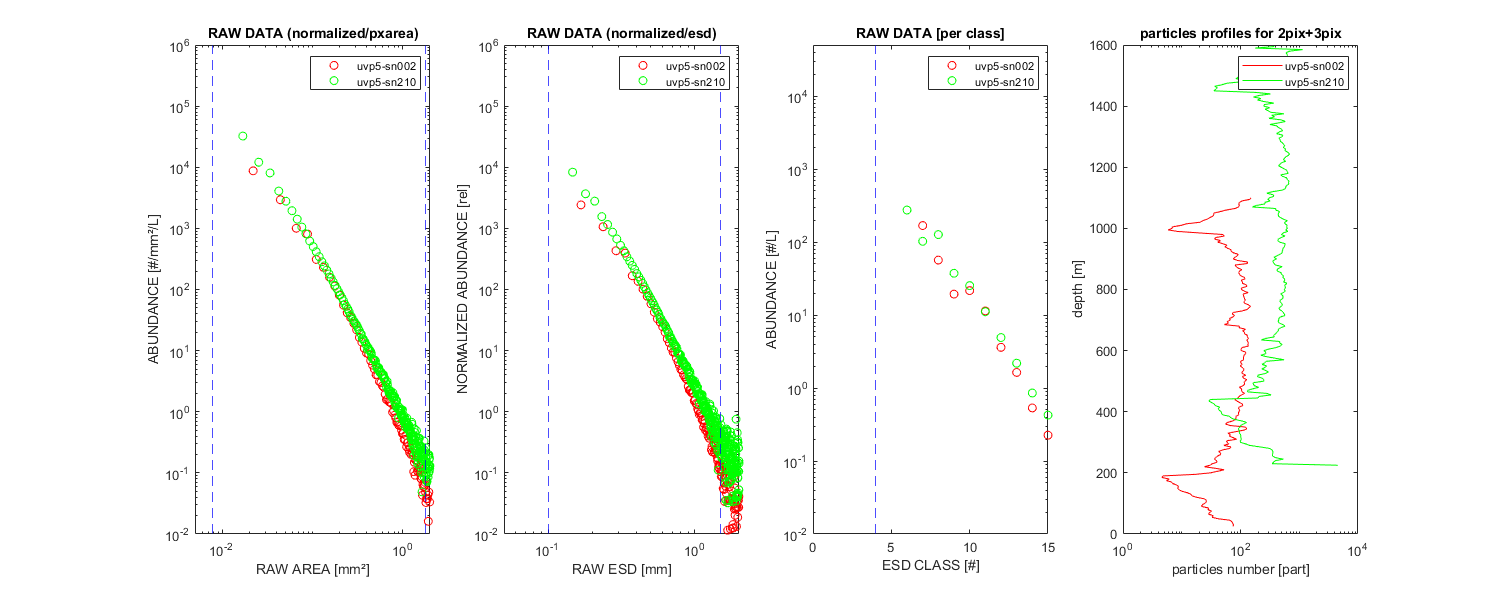

[Fit_range] = calibration_uvp_settings_a_cor;

## Fitting on reference data

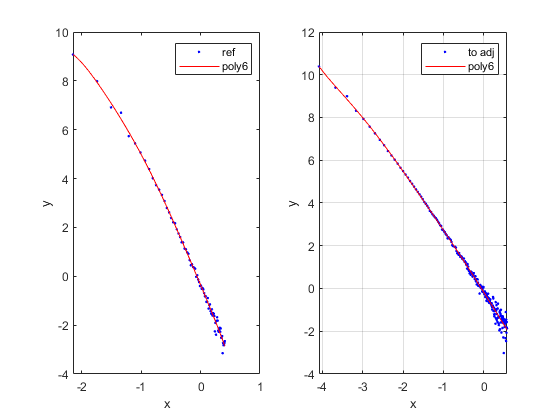

[fitresult] = create_two_fits(ref_esd_calib_log,log(ref_histo_mm2_vol_mean),fit_type,1,log([1:numel(adj_histo_mm2_vol_mean)].*(pix_adj^2)),log(adj_histo_mm2_vol_mean),Fit_range);  

[datahistref] = poly_from_fit(ref_esd_calib_log,fitresult,fit_type);

## Processing calibration

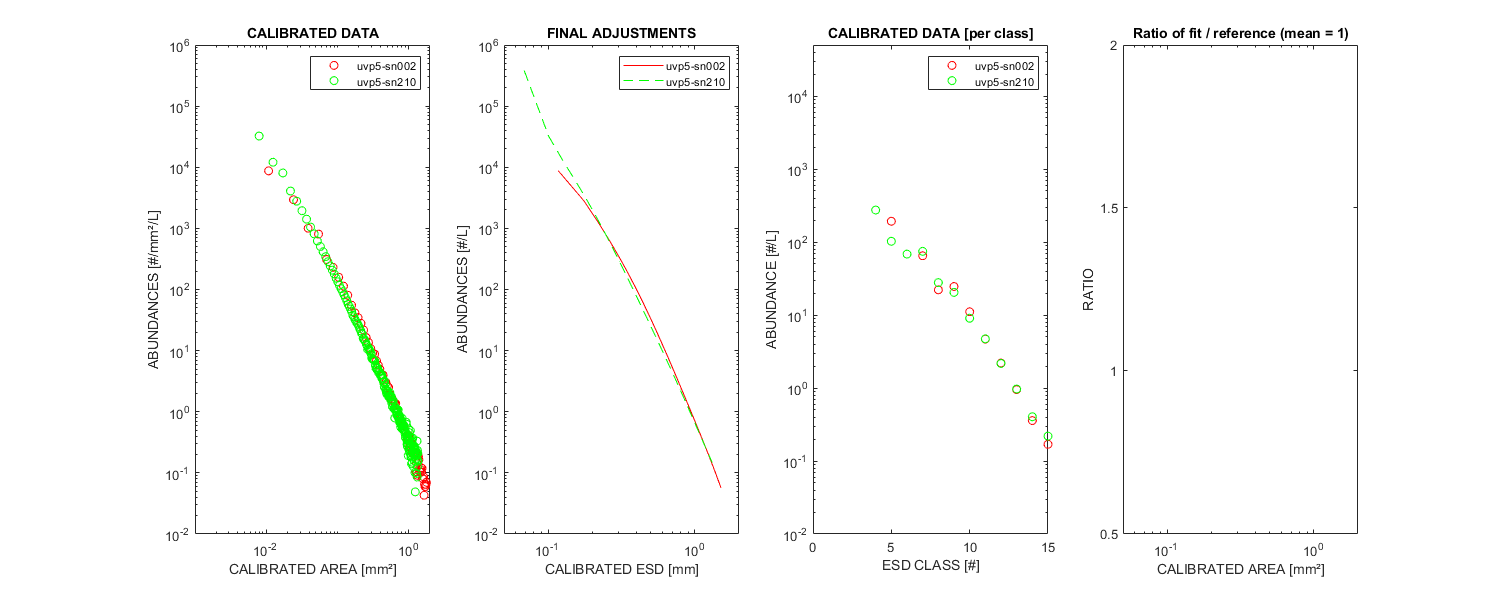

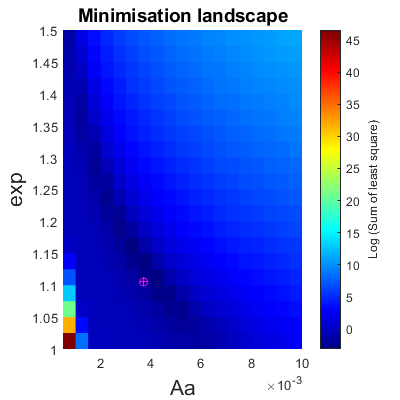

[X,feval]=fminsearch('histofunction7_new',X0);
aa_adj = X(1);
expo_adj = X(2);
calibration_uvp_settings_b;

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

## Results

Calibration_uvp_results

-------------------------------------------------------------------------
Processing date     : 2020-03-25 16:59:30
-------------------------------------------------------------------------
Min ESD       [mm]  : 0.1
Max ESD       [mm]  : 1.5
Mnimisation start   : [0.0046552 1.1]
Fit                 : poly6
EC factor           : 0.5
EC                  : 0.032014
Ratio (after adjust): 1
-------------------------------------------------------------------------
Reference UVP       : uvp5-sn002
Light 1             :  h002
Light 2             :  h029
Reference folder    : uvp5_sn002_intercalibrage_bassin_20180815
Reference profile   : 20181017084706
Reference profile # : 8
Shutter             : 0
Gain                : 6
Threshold           : 21
Exposure            : 9999
SMBase              : 0
Image volume [L]    : 0.96
Pixel        [µm]   : 0.1484
Pixel Area   [µm²]  : 0.022023
Aa                  : 0.0108
Exp                 : 1.165
-------------------------------------------------------